clear all;
load('velocity_scatter.mat');
[xData, yData, zData] = prepareSurfaceData( x, y, v );
ft = fittype( 'lowess' );
opts = fitoptions( 'Method', 'LowessFit' );
opts.Normalize = 'on';
opts.Span = 0.05;
[fitresult, gof] = fit( [xData, yData], zData, ft, opts );

yi = -40:5:160;
zi = -130:5:70;
[yi, zi] = meshgrid(yi,zi);
vi = fitresult(yi, zi)

vi =    -2.1174   -0.5219    0.6590    1.5177    2.1154    2.7059    2.7667    3.1729    3.3149    6.5128    3.6058    2.5003    3.1572    3.9563    4.7471    6.4226    8.4972    8.9708    8.5554    8.8031   12.6584   15.5622   18.0514   18.7232   19.3041   20.1973   21.1029   21.1078   18.1339   13.0059   11.8665   12.1765   12.9067   13.5672   12.2093   10.6810    8.5804    5.9724    2.9764   -0.3144   -3.8146
   -1.3360    0.8699    2.7350    4.1712    5.1516    5.7404    6.1240    6.2755    6.4585   10.4997    8.0045    5.8545    5.7021    6.3104    6.8351    8.8383   10.8362   11.5244   12.3273   17.3779   24.5174   28.9293   29.9614   29.3428   29.4355   30.1231   30.6197   30.7687   27.1067   21.8632   20.5649   20.6092   20.6552   19.9122   17.8128   15.2017   12.1372    8.7423    5.1081    1.3365   -2.6518
   -0.5059    2.3283    4.9466    7.2781    9.2405   10.7165   11.6136   11.8564   11.4056   15.8194   17.0607   10.9179    8.1842    8.4517    9.2354   11.4421   13.1408   

vi(1,:) = 0;
vi(end,:) = 0;
vi(:,1) = 0;
vi(:,end) = 0;

yi = -40:5:160;
zi = -130:5:70;
xi = 0:5:400;
[xi,yi,zi] = meshgrid(xi,yi,zi);
vAll = xi;
m = size(xi);
m = m(2);
for i = 1:m
    vAll(:,i,:) = vi;
end
X_tec=reshape(xi,[],1);
Y_tec=reshape(yi,[],1);
Z_tec=reshape(zi,[],1);
U_tec=reshape(vAll,[],1);


%

NewV = vi * 7;
V = sum(NewV * 5 * 5, 'all') / 200/200

V = 362.1022

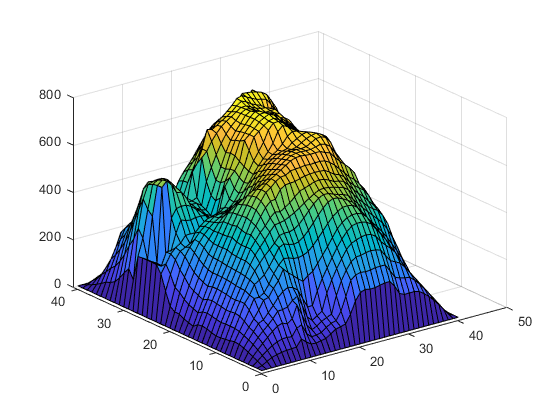

figure()
surf(NewV)

save('data.mat','NewV', 'yi', 'zi');


tec = [X_tec,Y_tec,Z_tec,U_tec];
dlmwrite('result.txt',tec,'delimiter','\t');

yi = 0:5:200;
zi = 0:5:200;
[yi, zi] = meshgrid(yi,zi);
NewV1 = NaN(size(NewV));
NewV1(:, 3:39) = NewV(:,5:41);
[m,n] = size(NewV1)

m = 41

n = 41


[xData, yData, zData] = prepareSurfaceData( yi, zi, NewV1 );

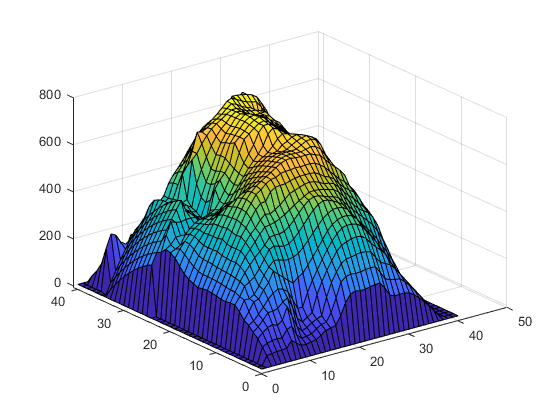


% Set up fittype and options.
ft = fittype( 'poly22' );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Robust = 'Bisquare';

% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, opts );

for i = 1:m
    for j = 1:n
        if yi(i,j) < 40 && zi(i,j) > 120 && zi(i,j) < 180
            NewV1(i,j) = fitresult(yi(i,j), zi(i,j));
        end
    end
end
NewV1(1,:) = 0;
NewV1(end,:) = 0;
NewV1(:,1) = 0;
NewV1(:,end) = 0;
NewV1(isnan(NewV1))=0;
figure()
surf(NewV1)


xi = ones(m,n); xi = xi * 200;
vi = zeros(m,n); wi = vi;
X_tec=reshape(xi,[],1);
Y_tec=reshape(yi,[],1);
Z_tec=reshape(zi,[],1);
U_tec=reshape(NewV1,[],1);
V_tec=reshape(vi,[],1);
W_tec=reshape(wi,[],1);
tec = [X_tec,Y_tec,Z_tec,U_tec, V_tec, W_tec];
dlmwrite('result.txt',tec,'delimiter','\t');
%[yi,zi] = meshgrid(yi,zi);

sum(NewV1 * 5 * 5, 'all') /10^9 * 60

ans = 0.8336

data = readtable('simulation.csv');

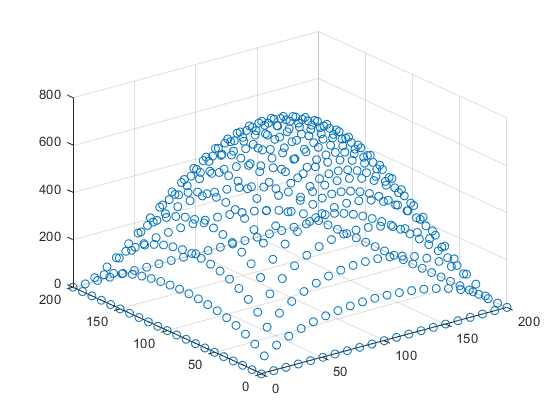

data = data{:,:};
yr = data(:,2); yr = yr * 1000000; 
zr = data(:,3); zr = zr * 1000000; zr = -zr;

ur = data(:,4); ur = ur * 1000;
figure()
scatter3(yr,zr,ur)


[xData, yData, zData] = prepareSurfaceData( yr, zr, ur );

% Set up fittype and options.
ft = 'linearinterp';

% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );

yr = 0:5:200;
zr = 0:5:200;
[yr, zr] = meshgrid(yr,zr);
ur = ones(m,n);
for i=1:m
    for j = 1:n
        ur(i,j) = fitresult(yr(i,j), zr(i,j));
    end
end



Z level compare

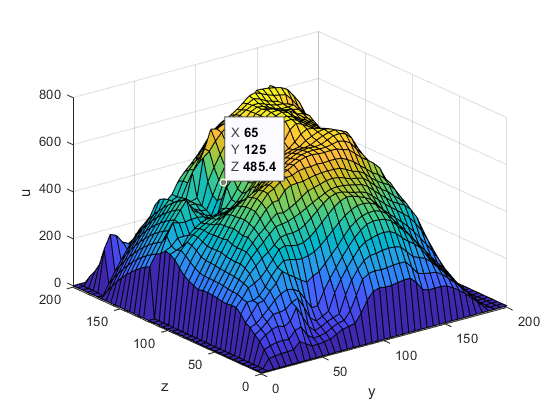

figure()
surf(yi,zi,NewV1);
xlabel('y'); ylabel('z'); zlabel('u');

ui = NewV1;
z_level = 100 % Center

z_level = 100

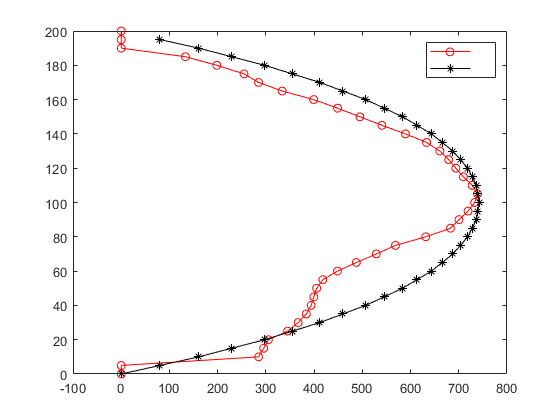

ans = 0.1472

index = 23;
y_exp = yi(index,:); u_exp = ui(index,:);
figure()
plot(u_exp, y_exp, 'or-');
hold on
y_sim = yr(21,:); u_sim = ur(21,:);
plot(u_sim,y_sim,'*k-');
legend('', '');

error = aaa./ui * 100;

figure()
y_exp = [];
u_exp = [];
ui = NewV1;
for i = 1:m
    y_exp = [y_exp, sqrt(yi(i,i)^2 + zi(i,i)^2)];
    u_exp = [u_exp, ui(i,i)];
end
y_sim = [];
u_sim = [];
for i = 1:m
    y_sim = [y_sim, sqrt(yr(i,i)^2 + zr(i,i)^2)];
    u_sim = [u_sim, ur(i,i)];
end

y_exp_q = linspace(min(y_exp), max(y_exp), 26);
u_exp_q = interp1(y_exp, u_exp, y_exp_q, 'cubic');

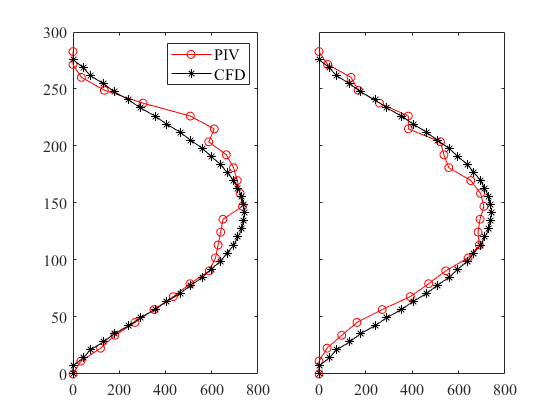


figure()
subplot(1,2,1)
plot(u_exp_q, y_exp_q, 'or-');
hold on

plot(u_sim,y_sim,'*k-');
xlim([0,800])
legend('PIV', 'CFD','FontSize', 12, 'FontName', 'Times New Roman');
set(gca,'FontSize',12,'FontName', 'Times New Roman')


y_exp = [];
u_exp = [];
ui = NewV1;
for i = 1:m
    y_exp = [y_exp, sqrt(yi(i,i)^2 + zi(i,i)^2)];
    u_exp = [u_exp, ui(i,42-i)];
end
y_sim = [];
u_sim = [];
for i = 1:m
    y_sim = [y_sim, sqrt(yr(i,i)^2 + zr(i,i)^2)];
    u_sim = [u_sim, ur(i,i)];
end

y_exp_q = linspace(min(y_exp), max(y_exp), 26);
u_exp_q = interp1(y_exp, u_exp, y_exp_q,'makima');

subplot(1,2,2)
plot(u_exp_q, y_exp_q, 'or-');
hold on

plot(u_sim,y_sim,'*k-');
xlim([0,800])
set(gca,'yticklabel',[])
set(gca,'FontSize',12,'FontName', 'Times New Roman')